# **Tracker Tutorial **

### **General Informaiton**

The tracker class creates tracker objects that use the mathematical linear model of a double integral of accerlation to predict the next position and for the velocity it is the single integral of accerlation. We are using a linear model, because the changes in position are relatively are relatively small allowing for more linear behavior. 

### Constructor

To create a tracker object, the only information that is needed is initial position and velocity of the new object to be tracked. The position and velocity needs to be in 3 dimensions because it is using real life cordinates systems, with a reference to some origin. The distance will be Eulcidean distance from some origin reference point in the simulation. The following code snippet shows how to create a tracker object and how the properties are stored within the tracker. The public 

% Set up the variables
pos = [1,2,3];
velocity = [1,1,1];

% Put Variables into 6x1 Vector
param = [transpose(pos); transpose(velocity)];

% Creation of tracker object
tracker = Tracker(param);

### Update Kalman Filter

The main purpose of the tracker object is to update the state's predicted position by using the observeration data. The observeration data in our simulation is the sensory information gathered from the radars, and the gps reporting from the UAS object itself. 

The method that will update the Kalman filter needs certain parameters: telemetry informaiton, sensory information, and the time that has past since the last update. The segement of code below shows how to update the kalman filter.

% Create new Observeration Data
tnew = table();
tnew.ID = "1";
tnew.pos = [2,3,4] + rand(1,3);
tnew.speed = [1,1,1] + rand(1,3);
tnew.time = 1;
telemetry = tnew;
tnew.pos = [2,3,4] + rand(1,3);
tnew.speed = [1,1,1] + rand(1,3);
tnew.time = 1;
sensory = tnew;

% Update the Kalman Filter For That Data
tracker.RecieveObservationData(telemetry, sensory);
tracker.UpdateModel(1);

### Tracking Objects During A Flight

Now that we understand how the tracker is created and how it updates its predicted state. Now lets look at the Tracker object working with a simple flight through a simple lane system. This example will be looking at a UAS that doesn't have any rogue behavior, and the tracker will be updating with every simulation step of 1 sec. 

The First segment of code is just setting up the lane system, and a random uas trajectory and radar's in the simulation. 

% Set up a lane system 
lbsd = LBSD.genSampleLanes(10, 15);
sim = Sim();
sim.lbsd = lbsd;
sim.initialize();

radarsList = sim.radar_list;
uas = sim.uas_list(1);

tnew = table();
tnew.ID = "";
tnew.pos = zeros(1,3);
tnew.speed = zeros(1,3);
tnew.time = 0;
radars = tnew;
telemetry = tnew;

param = [uas.gps.lon; uas.gps.lat; uas.gps.alt;...
    uas.gps.vx; uas.gps.vy; uas.gps.vz];

tracker = Tracker(param);

The next segment of code is the actual simulation of running the flight trajectory of UAS and Radars while tracking with a tracker object. While running this simulation we will be gathering the reported, observed, and predicted sets to see how well the tracker object is doing to track the UAS in the simulation. 

% Set up Variables
tel = [];
sen = [];
pred = [];
pos = [uas.gps.lon; uas.gps.lat; uas.gps.alt; ...
    uas.gps.vx; uas.gps.vy; uas.gps.vz];

res = sim.lbsd.getReservations();
minTime = min(res.entry_time_s);
maxTime = max(res.exit_time_s);
num_steps = floor((maxTime - minTime)/sim.step_rate_hz);

del_t = 1;
sim.atoc.time = minTime;
time = minTime;
for numradar = 1:length(sim.radar_list)
    sim.radar_list(numradar).time = minTime;
end
sim.uas_list = uas;

for i = 1:num_steps
    uas_step = uas.stepTrajectory();
    if uas.active
        pos = uas.exec_traj;
        if ~isempty(pos)
            uas.gps.lon = pos(uas_step, 1);
            uas.gps.lat = pos(uas_step, 2);
            uas.gps.alt = pos(uas_step, 3);
            uas.gps.commit();
            traj = uas.exec_traj;
            set(uas.h, 'XData', traj(:,1), ...
               'YData', traj(:,2), ...
               'ZData', traj(:,3));
        end
        sim.step(del_t);
        time = time + del_t;
        index = 1;
        for num = 1:size(sim.radar_list)
            radar = sim.radar_list(num);
            if(~isempty(radar.targets))
                for item = 1:size(radar.targets, 2)
                    radars{index, {'ID', 'pos', 'speed', 'time'}}...
                            = ["", zeros(1,3), zeros(1,3), 0];

                    pos = [radar.targets(item).x, ...
                            radar.targets(item).y, radar.targets(item).z];
                    speed = [radar.targets(item).s];

                    radars.ID(index) = radar.ID;
                    radars.pos(index, :) = pos;
                    radars.speed(index, :) = speed;
                    radars.time(index) = radar.time;
                    
                    index = index + 1;
                    sen = [sen; pos];
                end
            end
        end
        telemetry.pos = [uas.gps.lon, uas.gps.lat, uas.gps.alt];
        telemetry.speed = [uas.gps.vx, uas.gps.vy, uas.gps.vz];
        
        if(height(radars) == 1)
            radars = [];
        end
        tracker.RecieveObservationData(telemetry, radars);
        tracker.UpdateModel(del_t);
        pred = [pred; transpose(tracker.pos(1:3))];
        tel = [tel; [uas.gps.lon, uas.gps.lat, uas.gps.alt]];
        radars = tnew;
    end
end


### Plotting The Results Of The Tracker Object 

This segment of the code plots the reported telemetry informaiton from the UAS object through a flight object, along with the predicted state from the kalman filter. This plot is shown in the top figure, the bottom figure dispalys the sensory information from the radars that were used to make the kalman filter. 

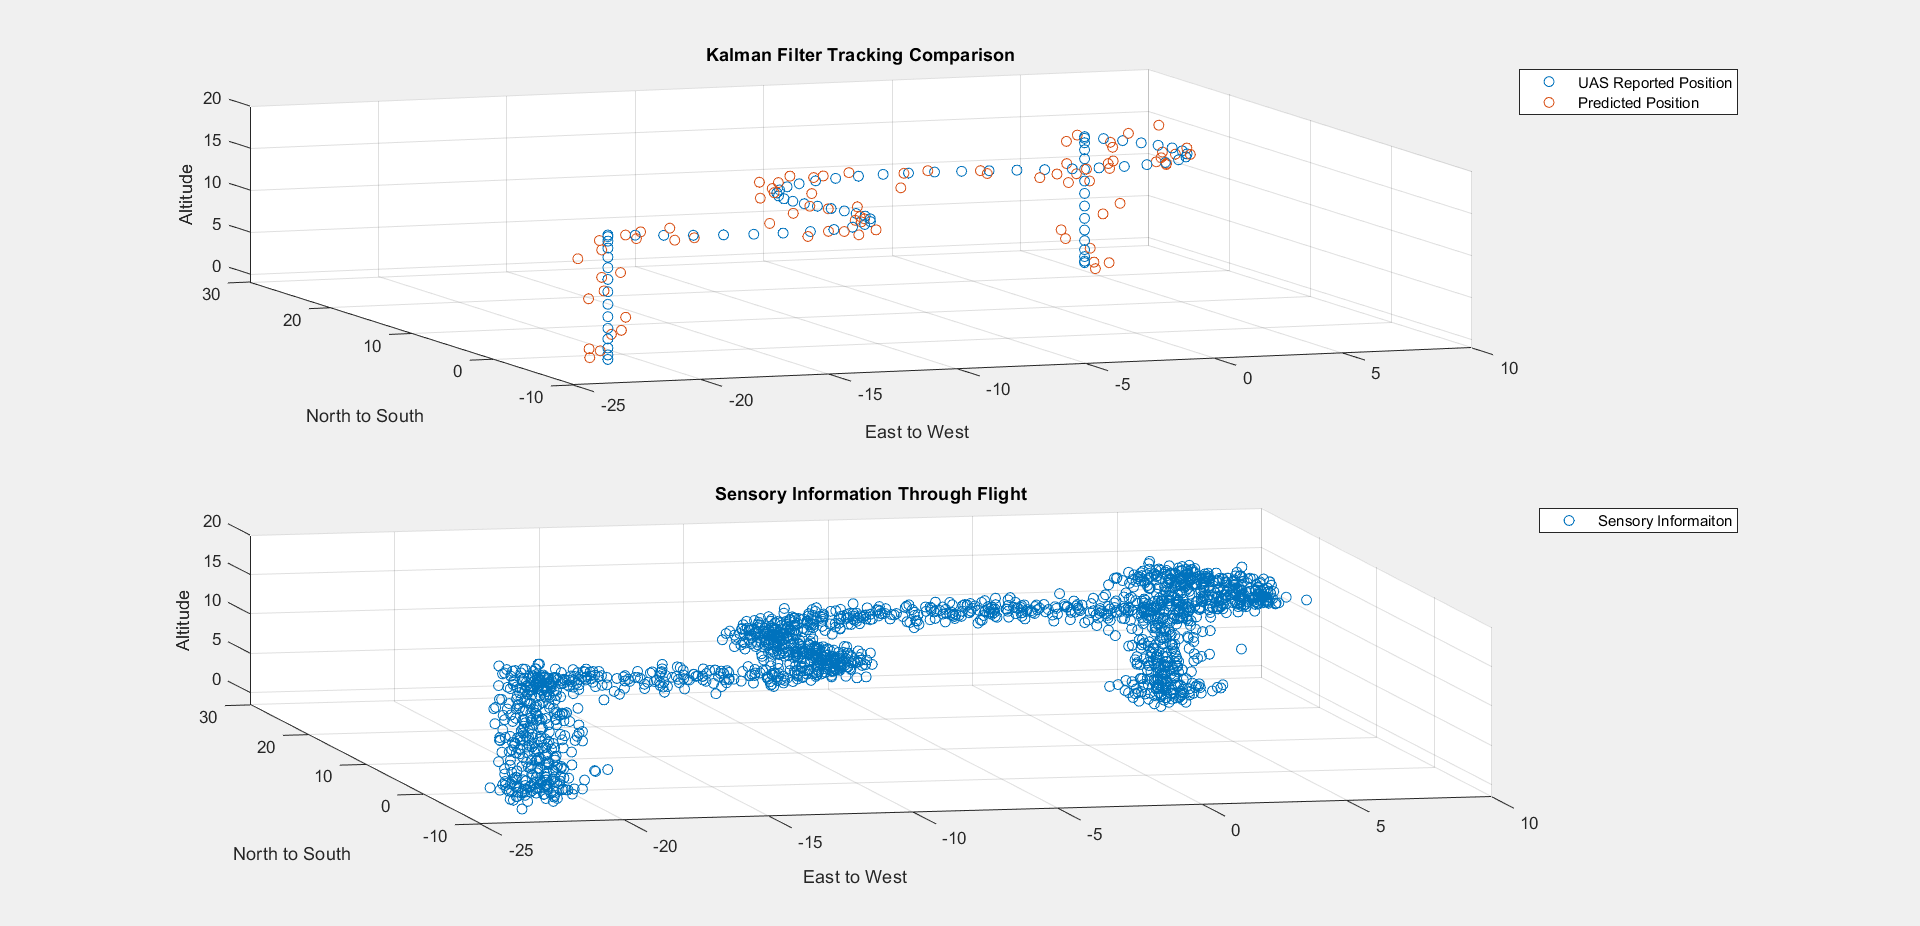

subplot(2,1,1);
h = scatter3(tel(:, 1), tel(:, 2), tel(:, 3), DisplayName="UAS Reported Position", Color="red");
ax = ancestor(h, 'axes');
f = ancestor(h, 'figure');
f.Visible = true;
hold on;
scatter3(pred(:,1), pred(:,2), pred(:,3), DisplayName="Predicted Position", Color="Blue");
xlabel("East to West");
ylabel("North to South");
zlabel("Altitude");
title("Kalman Filter Tracking Comparison");
legend
subplot(2,1,2)
scatter3(sen(:, 1), sen(:, 2), sen(:, 3), DisplayName="Sensory Informaiton", Color="Pink");
xlabel("East to West");
ylabel("North to South");
zlabel("Altitude");
title("Sensory Information Through Flight");
legend
hold off;

### Results

The graph of the previous segment seems to show that the Kalman filter tracks pretty closely to the reported UAS information, and the sensory informaiton. However, to explore this even further, I performed a couple of tests to measure the difference between the reported and the predicted Kalman filter position. 

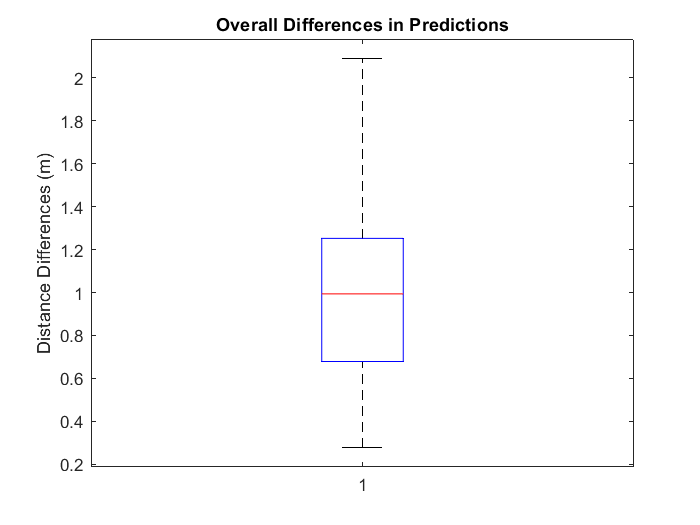

stepDifference = ones(size(tel, 1), 1);
for step = 1:length(stepDifference)
    stepDifference(step) = norm(tel(step, :) - pred(step, :));
end
% Calculate the difference
figure;
h = boxplot(stepDifference);
ylabel("Distance Differences (m)");
title("Overall Differences in Predictions");

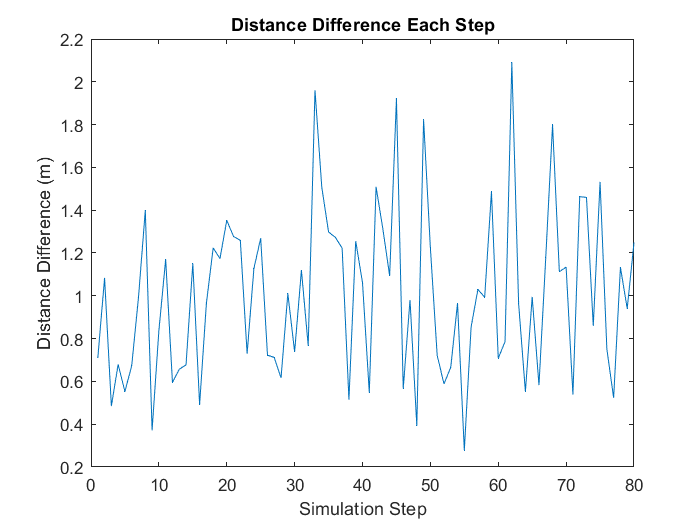


figure;
x = 1:size(stepDifference, 1);
plot(x, stepDifference)
title("Distance Difference Each Step");
xlabel("Simulation Step")
ylabel("Distance Difference (m)");

Looking at the two graphs looking at the difference between the reported and predicted positions is between 0 and 2 meters of differences. The only problem that it has, is it doesn't holen in on the uas reported before, and this could be a result of the turns around the roundabouts, causing a sudden change that it has to correct its prediction. However, overall it keeps up with the UAS trajectory pretty well. 